# Revision del dataset Iris paso a paso

Antes de meterle una red al dataset hay que mirarlo. Cada seccion deja una tabla en el workspace: crudo, sin outliers, balanceado, estandarizado y normalizado. Con esas cinco tablas R3 entrena el perceptron y el Adaline del taller para ver que paso le sirve a la neurona.

clear; close all; clc

## Paso 0: cargar y mirar el dato crudo

150 flores, 4 medidas en centimetros y la especie (3 clases de 50).

iris = load('iris.dat');
T = array2table(iris(:, 1:4), 'VariableNames', ...
    {'largo_sepalo', 'ancho_sepalo', 'largo_petalo', 'ancho_petalo'});
T.clase = categorical(iris(:, 5), 1:3, {'setosa', 'versicolor', 'virginica'});
vars = T.Properties.VariableNames(1:4);

T0_crudo = T;
disp(head(T0_crudo))

    largo_sepalo    ancho_sepalo    largo_petalo    ancho_petalo    clase 
    ____________    ____________    ____________    ____________    ______

        5.1             3.5             1.4             0.2         setosa
        4.9               3             1.4             0.2         setosa
        4.7             3.2             1.3             0.2         setosa
        4.6             3.1             1.5             0.2         setosa
          5             3.6             1.4             0.2         setosa
        5.4             3.9             1.7             0.4         setosa
        4.6             3.4             1.4             0.3         setosa
          5             3.4             1.5             0.2         setosa



summary(T0_crudo)


T0_crudo: 150×5 table

Variables:

    largo_sepalo: double
    ancho_sepalo: double
    largo_petalo: double
    ancho_petalo: double
    clase: categorical (3 categories)

Statistics for applicable variables:

                    NumMissing       Min          Median         Max           Mean          Std    

    largo_sepalo        0           4.3000        5.8000        7.9000        5.8433        0.8281  
    ancho_sepalo        0                2             3        4.4000        3.0573        0.4359  
    largo_petalo        0                1        4.3500        6.9000        3.7580        1.7653  
    ancho_petalo        0           0.1000        1.3000        2.5000        1.1993        0.7622  
    clase               0                                                                           



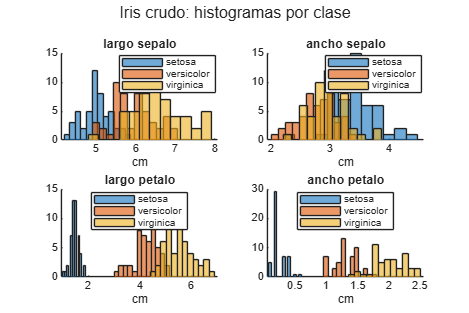


% distribucion de cada variable, separando por clase
figure('Position', [100 100 900 600]);
for k = 1:4
    subplot(2, 2, k); hold on
    for c = categories(T.clase)'
        histogram(T.(vars{k})(T.clase == c{1}), 12, 'DisplayName', c{1});
    end
    title(strrep(vars{k}, '_', ' ')); xlabel('cm'); legend('Location', 'best');
end
sgtitle('Iris crudo: histogramas por clase');
guardar_fig('rev_iris_histogramas');

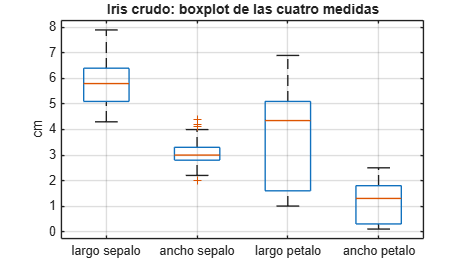


% boxplot de las cuatro juntas: estan todas en cm y en rangos parecidos
figure('Position', [100 100 700 400]);
boxplot(T{:, vars}, 'Labels', strrep(vars, '_', ' ')); ylabel('cm'); grid on
title('Iris crudo: boxplot de las cuatro medidas');
guardar_fig('rev_iris_boxplot_crudo');

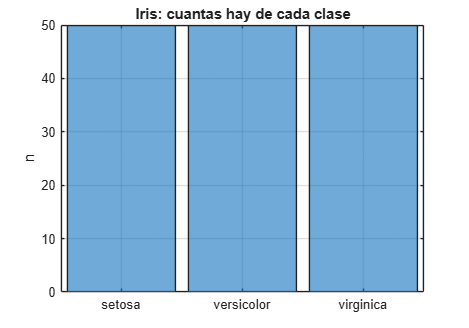


% balance de la clase
figure('Position', [100 100 500 350]);
histogram(T.clase); ylabel('n'); title('Iris: cuantas hay de cada clase'); grid on
guardar_fig('rev_iris_balance');

disp(table(categories(T.clase), countcats(T.clase), 'VariableNames', {'clase', 'n'}))

        clase         n 
    ______________    __

    {'setosa'    }    50
    {'versicolor'}    50
    {'virginica' }    50



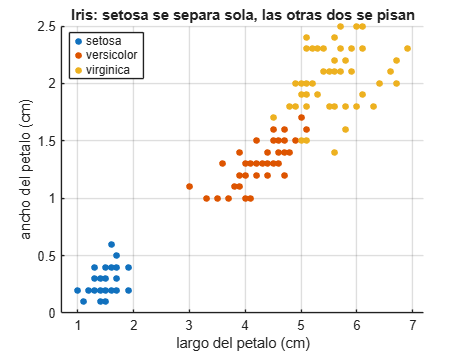


% dispersion: con largo y ancho del petalo ya se ve casi todo
figure('Position', [100 100 600 450]);
gscatter(T.largo_petalo, T.ancho_petalo, T.clase);
xlabel('largo del petalo (cm)'); ylabel('ancho del petalo (cm)'); grid on
title('Iris: setosa se separa sola, las otras dos se pisan');
guardar_fig('rev_iris_dispersion');


% Lo que se ve: las clases estan perfectamente balanceadas (50, 50, 50),
% las medidas estan todas en cm y en rangos parecidos, setosa se separa
% de las otras dos con cualquier medida del petalo, y versicolor y
% virginica se traslapan un poco.

## Paso 1: corregir outliers

Regla del 1.5*IQR: lo que se sale se recorta al borde, no se borra la fila (con 150 datos no sobran).

T1_outliers = T0_crudo;
for k = 1:4
    x = T1_outliers.(vars{k});
    q = quantile(x, [0.25 0.75]);
    li = q(1) - 1.5*(q(2)-q(1));
    ls = q(2) + 1.5*(q(2)-q(1));
    fprintf('%-13s: %d valores fuera de [%.2f, %.2f]\n', vars{k}, sum(x<li | x>ls), li, ls);
    x(x < li) = li;  x(x > ls) = ls;
    T1_outliers.(vars{k}) = x;
end

largo_sepalo : 0 valores fuera de [3.15, 8.35]
ancho_sepalo : 4 valores fuera de [2.05, 4.05]
largo_petalo : 0 valores fuera de [-3.65, 10.35]
ancho_petalo : 0 valores fuera de [-1.95, 4.05]


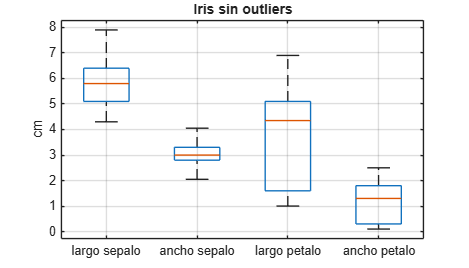


figure('Position', [100 100 700 400]);
boxplot(T1_outliers{:, vars}, 'Labels', strrep(vars, '_', ' ')); ylabel('cm'); grid on
title('Iris sin outliers');
guardar_fig('rev_iris_boxplot_outliers');


% Solo ancho del sepalo tenia unos pocos valores fuera. Casi no cambia nada.

## Paso 2: balancear las clases

Iris ya viene balanceado, 50 de cada una. No hay nada que hacer, pero se deja la tabla con el mismo nombre para seguir el orden de los pasos.

T2_balanceado = T1_outliers;
disp(table(categories(T2_balanceado.clase), countcats(T2_balanceado.clase), 'VariableNames', {'clase', 'n'}))

        clase         n 
    ______________    __

    {'setosa'    }    50
    {'versicolor'}    50
    {'virginica' }    50



## Paso 3: estandarizar (media 0, desviacion 1)

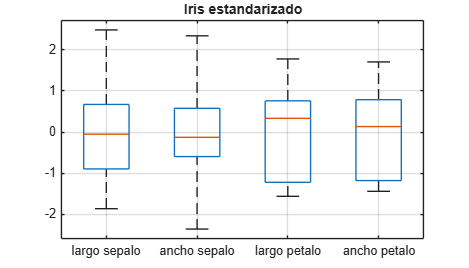

T3_estandarizado = T2_balanceado;
for k = 1:4
    T3_estandarizado.(vars{k}) = zscore(T2_balanceado.(vars{k}));
end
figure('Position', [100 100 700 400]);
boxplot(T3_estandarizado{:, vars}, 'Labels', strrep(vars, '_', ' ')); grid on
title('Iris estandarizado');
guardar_fig('rev_iris_boxplot_estandarizado');

## Paso 4: normalizar (entre 0 y 1)

Parte del balanceado, no del estandarizado. Son dos alternativas.

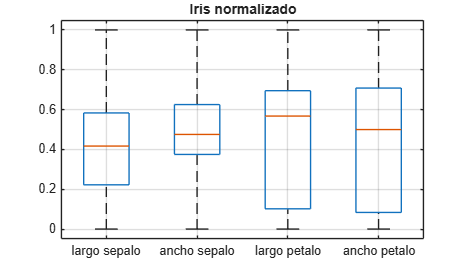

T4_normalizado = T2_balanceado;
for k = 1:4
    x = T2_balanceado.(vars{k});
    T4_normalizado.(vars{k}) = (x - min(x)) / (max(x) - min(x));
end
figure('Position', [100 100 700 400]);
boxplot(T4_normalizado{:, vars}, 'Labels', strrep(vars, '_', ' ')); grid on
title('Iris normalizado');
guardar_fig('rev_iris_boxplot_normalizado');

## Resumen

disp('Tablas listas, una por paso:')

Tablas listas, una por paso:


disp({'T0_crudo'; 'T1_outliers'; 'T2_balanceado'; 'T3_estandarizado'; 'T4_normalizado'})

    {'T0_crudo'        }
    {'T1_outliers'     }
    {'T2_balanceado'   }
    {'T3_estandarizado'}
    {'T4_normalizado'  }




% se guardan para que R3 las use con el perceptron y el Adaline
save('iris_pasos.mat', 'T0_crudo', 'T1_outliers', 'T2_balanceado', 'T3_estandarizado', 'T4_normalizado');